Variables independientes $\theta_1 ,\theta_2 ,\;X_a ,\;Z_a$

clear
clc

b=2.3;
h=0.675;
n=100;
xi=linspace(-0.5*h,0.5*h,n);
yi=linspace(-0.5*b,0.5*b,n);
[X,Y] = meshgrid(xi,yi);
Z = zeros(size(X));

Pix=h/2;
Piy=b/2;
Piz=0.5;



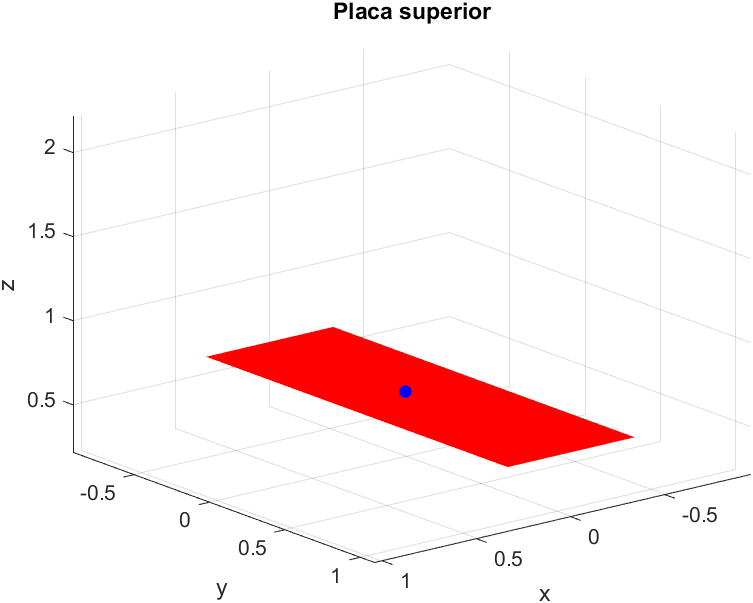



Pi=[Pix Piy Piz]

Pi =     0.3375    1.1500    0.5000



beta=18;
theta=20;
Xa=00;
Za=0;

Pf=Pos(Pi,theta,beta,Za,Xa,h,b) %vector normal

Pf =     0.4807    0.9477    0.6893


pf2=PosFinal(Pi,theta,beta,Za,Xa) % Todo por componentes

pf2 =     0.4882    0.9392    0.6853


pf3=PosFinal2(Pi,theta,beta,Za,Xa) % Matriz de transformación

pf3 =     0.2973    1.2517    0.1771




pf2-Pf

ans =     0.0075   -0.0085   -0.0040


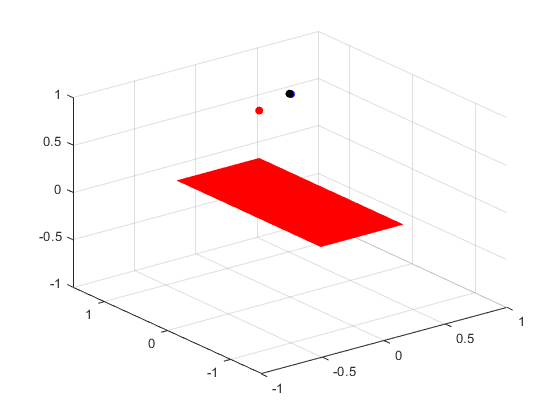


scatter3(Pi(1),Pi(2),Pi(3),'filled','r')
hold on
scatter3(Pf(1),Pf(2),Pf(3),'filled','k')
scatter3(pf2(1),pf2(2),pf2(3),'filled','b')
%scatter3(pf3(1),pf3(2),pf3(3),'filled','y')
surf(X,Y,Z,"EdgeColor","none","FaceColor","r")
hold off
xlim([-1 1])
ylim([-1.5 1.5])
zlim([-1 1])

Movimientos para el punto Pi

PfBalanceo=ones([37 3]);
PfCabeceo=ones([41 3]);
PfAvance=ones([51 3]);
PfArfada=ones([51 3]);

for i=1:37
    PfBalanceo(i,:)=Pos(Pi,0,i-19,0,0,h,b);
end

for i=1:41
    PfCabeceo(i,:)=Pos(Pi,i-21,0,0,0,h,b);
end

for i=1:51
    PfAvance(i,:)=Pos(Pi,0,0,0,(i-1)/51*0.3,h,b);
end

for i=1:51
    PfArfada(i,:)=Pos(Pi,0,0,(i-1)/51*0.2,0,h,b);
end


$$ans = \frac{\partial }{\partial t}\mathrm{Ftheta}\left(t\right)$$

Gráficas de movimiento

    1. Balanceo

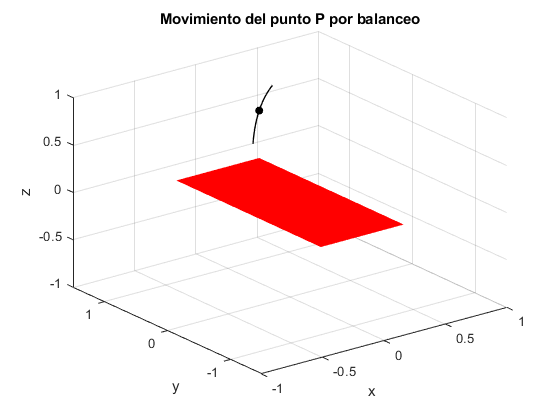

plot3(PfBalanceo(:,1),PfBalanceo(:,2),PfBalanceo(:,3),'k',"LineWidth",1)
hold on
surf(X,Y,Z,"EdgeColor","none","FaceColor","r")
scatter3(Pi(1),Pi(2),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("y")
zlabel("z")
xlim([-1 1])
ylim([-1.5 1.5])
zlim([-1 1])
grid on
title("Movimiento del punto P por balanceo")

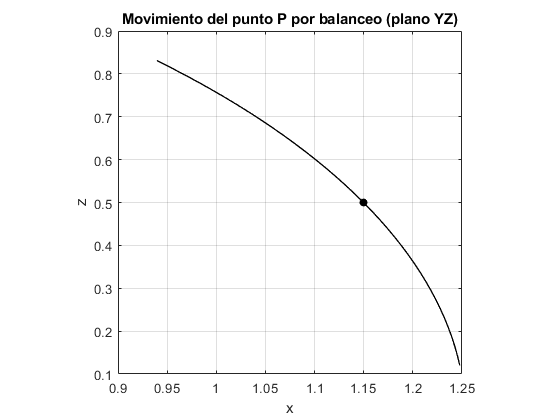

plot(PfBalanceo(:,2),PfBalanceo(:,3),'k',"LineWidth",1)
hold on 
scatter(Pi(2),Pi(3),'filled','k')
hold off
ylabel("z")
xlabel("x")
axis("square")
grid on
title("Movimiento del punto P por balanceo (plano YZ)")

    2. Cabeceo

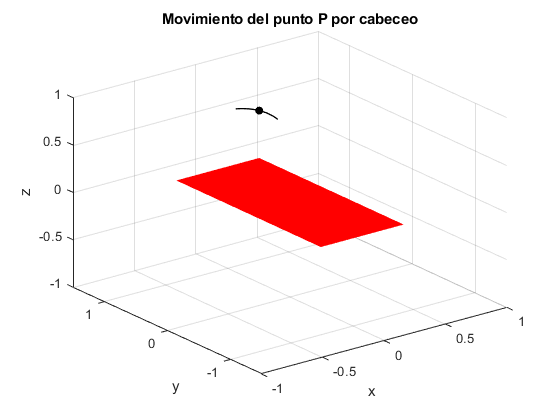

plot3(PfCabeceo(:,1),PfCabeceo(:,2),PfCabeceo(:,3),'k',"LineWidth",1)
hold on
surf(X,Y,Z,"EdgeColor","none","FaceColor","r")
scatter3(Pi(1),Pi(2),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("y")
zlabel("z")
xlim([-1 1])
ylim([-1.5 1.5])
zlim([-1 1])
grid on
title("Movimiento del punto P por cabeceo")

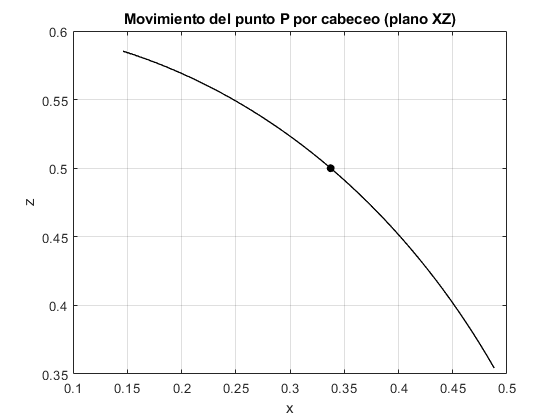


plot(PfCabeceo(:,1),PfCabeceo(:,3),'k',"LineWidth",1)
hold on 
scatter(Pi(1),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("z")
grid on
title("Movimiento del punto P por cabeceo (plano XZ)")

    3. Avance

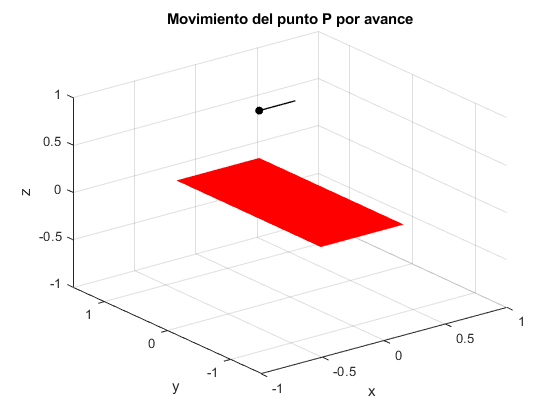

plot3(PfAvance(:,1),PfAvance(:,2),PfAvance(:,3),'k',"LineWidth",1)
hold on
surf(X,Y,Z,"EdgeColor","none","FaceColor","r")
scatter3(Pi(1),Pi(2),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("y")
zlabel("z")
xlim([-1 1])
ylim([-1.5 1.5])
zlim([-1 1])
grid on
title("Movimiento del punto P por avance")

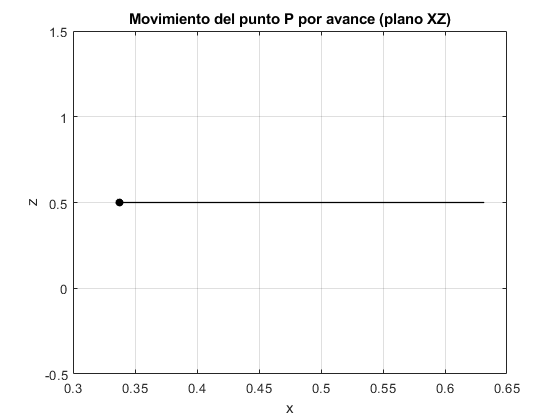

plot(PfAvance(:,1),PfAvance(:,3),'k',"LineWidth",1)
hold on 
scatter(Pi(1),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("z")
grid on
title("Movimiento del punto P por avance (plano XZ)")

    4. Arfada

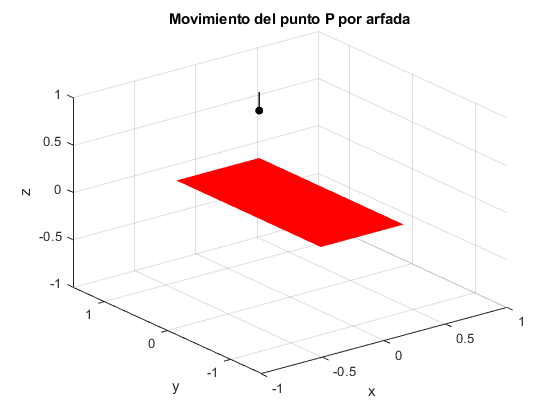

plot3(PfArfada(:,1),PfArfada(:,2),PfArfada(:,3),'k',"LineWidth",1)
hold on
surf(X,Y,Z,"EdgeColor","none","FaceColor","r")
scatter3(Pi(1),Pi(2),Pi(3),'filled','k')
hold off
xlabel("x")
ylabel("y")
zlabel("z")
xlim([-1 1])
ylim([-1.5 1.5])
zlim([-1 1])
grid on
title("Movimiento del punto P por arfada")

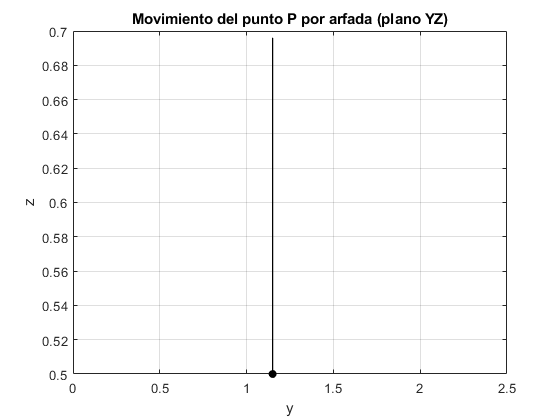

plot(PfArfada(:,2),PfArfada(:,3),'k',"LineWidth",1)
hold on 
scatter(Pi(2),Pi(3),'filled','k')
hold off
xlabel("y")
ylabel("z")
grid on
title("Movimiento del punto P por arfada (plano YZ)")

x-xcos(theta)

Z sen(theta)

deltaX= x(1-cos(theta))+Z sen(theta)

pfx=xi+deltaX

pfy=piycos(beta)-zsind(beta)

pfz=Za+

function [Pf] = Pos(Pi,theta,beta,Za,Xa,h,b)
Pfx=Pi(1).*cosd(theta)+Xa;
Pfy=Pi(2).*cosd(beta);
Pfz=-Pi(1).*sind(theta)+Pi(2).*sind(beta)+Za;
Pf=[Pfx Pfy Pfz]+Pi(3).*PlanoNormal(h,b,theta,beta,Za,Xa);
end

function [Pf] = PosFinal(Pi,theta,beta,Za,Xa)
Pfx=Pi(1).*(cosd(theta))+Pi(3).*sind(theta)+Xa;
Pfy=Pi(2).*cosd(beta)-Pi(3).*sind(beta);
Pfz=Za+Pi(3)-Pi(1).*sind(theta)+Pi(2).*sind(beta)-Pi(3).*(1-cosd(theta))-Pi(3).*(1-cosd(beta));
Pf=[Pfx Pfy Pfz];
end

function [Pf] = PosFinal2(Pi,theta,beta,Za,Xa)
Pf=Pi*[1 0 0;0 cosd(theta) -sind(theta);0 sind(theta) cosd(theta)]*[cosd(beta) 0 sind(beta); 0 1 0;-sind(beta) 0 cosd(beta)]+[Xa 0 Za];
end




function [N] = PlanoNormal(h,b,theta,beta,Za,Xa)
P1=PosPlanoNormal([0 0 0],theta,beta,Za, Xa);
P2=PosPlanoNormal([0.5*h 0 0],theta,beta,Za, Xa);
P3=PosPlanoNormal([0 0.5*b 0],theta,beta,Za, Xa);
N=cross(P2-P1,P3-P1)./norm(cross(P2-P1,P3-P1));
end

function [Pf] = PosPlanoNormal(Pi,theta,beta,Za,Xa)
Pfx=Pi(1).*cosd(theta)+Xa;
Pfy=Pi(2).*cosd(beta);
Pfz=-Pi(1).*sind(theta)+Pi(2).*sind(beta)+Za;
Pf=[Pfx Pfy Pfz];
end

